ng = 5

ng = 5

ns = 11

ns = 11

omega_c = PS_PRJ_1_Faza_2a(ng,ns)

omega_c = 1.5708


M = 29;
r = 90;
beta = 6;
L = 7;
alfa = 50;
omega_c = 1.5708;
freq_c = omega_c/pi

freq_c = 0.5000

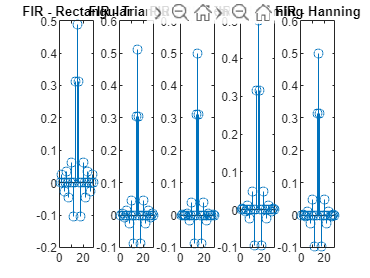


f_dr = fir1(M-1,freq_c,dr);
f_tr = fir1(M-1,freq_c,tr);
f_blm = fir1(M-1,freq_c,blm);
f_ham = fir1(M-1,freq_c,ham);
f_han = fir1(M-1,freq_c,han);
f_cheb = fir1(M-1,freq_c,cheb);
f_chebm5 = fir1(M-1,freq_c,chebm5);
f_chebp5 = fir1(M-1,freq_c,chebp5);
f_ksr = fir1(M-1,freq_c,ksr);
f_ksrm1 = fir1(M-1,freq_c,ksrm1);
f_ksrp1 = fir1(M-1,freq_c,ksrp1);
f_tuc = fir1(M-1,freq_c,tuc);
f_tucm15 = fir1(M-1,freq_c,tucm15);
f_tucp15 = fir1(M-1,freq_c,tucp15);
f_lan = fir1(M-1,freq_c,lan);
f_lanm1 = fir1(M-1,freq_c,lanm1);
f_lanp1 = fir1(M-1,freq_c,lanp1);

%Figura 8
figure;
subplot(1,5,1);
stem(f_dr);
title('FIR - Rectangular');

subplot(1,5,2);
stem(f_tr);
title('FIR - Triangular');

subplot(1,5,3);
stem(f_blm);
title('FIR - Blackman');

subplot(1,5,4);
stem(f_ham);
title('FIR - Hamming');

subplot(1,5,5);
stem(f_han);
title('FIR - Hanning');

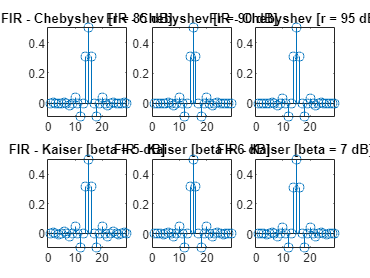


%Figura 9
figure;
subplot(2,3,1);
stem(f_chebm5);
title('FIR - Chebyshev [r = 85 dB]');

subplot(2,3,2);
stem(f_cheb);
title('FIR - Chebyshev [r = 90 dB]');

subplot(2,3,3);
stem(f_chebp5);
title('FIR - Chebyshev [r = 95 dB]');

subplot(2,3,4);
stem(f_ksrm1);
title('FIR - Kaiser [beta = 5 dB]');

subplot(2,3,5);
stem(f_ksr);
title('FIR - Kaiser [beta = 6 dB]');

subplot(2,3,6);
stem(f_ksrp1);
title('FIR - Kaiser [beta = 7 dB]');

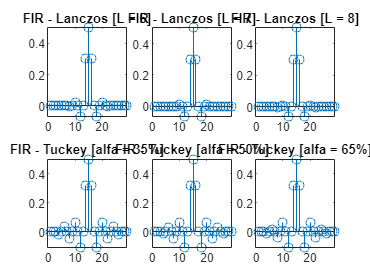


%Figura 10
figure;
subplot(2,3,1);
stem(f_lanm1);
title('FIR - Lanczos [L = 6]');

subplot(2,3,2);
stem(f_lan);
title('FIR - Lanczos [L = 7]');

subplot(2,3,3);
stem(f_lanp1);
title('FIR - Lanczos [L = 8]');

subplot(2,3,4);
stem(f_tucm15);
title('FIR - Tuckey [alfa = 35%]');

subplot(2,3,5);
stem(f_tuc);
title('FIR - Tuckey [alfa = 50%]');

subplot(2,3,6);
stem(f_tucp15);
title('FIR - Tuckey [alfa = 65%]');

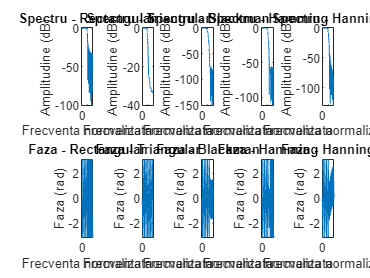


K = 5000;

[h_dr,w_dr] = freqz(f_dr,1,K);
[h_tr,w_tr] = freqz(f_tr,1,K);
[h_blm,w_blm] = freqz(f_blm,1,K);
[h_ham,w_ham] = freqz(f_ham,1,K);
[h_han,w_han] = freqz(f_han,1,K);
[h_cheb,w_cheb] = freqz(f_cheb,1,K);
[h_chebm5,w_chebm5] = freqz(f_chebm5,1,K);
[h_chebp5,w_chebp5] = freqz(f_chebp5,1,K);
[h_ksr,w_ksr] = freqz(f_ksr,1,K);
[h_ksrm1,w_ksrm1] = freqz(f_ksrm1,1,K);
[h_ksrp1,w_ksrp1] = freqz(f_ksrp1,1,K);
[h_tuc,w_tuc] = freqz(f_tuc,1,K);
[h_tucm15,w_tucm15] = freqz(f_tucm15,1,K);
[h_tucp15,w_tucp15] = freqz(f_tucp15,1,K);
[h_lan,w_lan] = freqz(f_lan,1,K);
[h_lanm1,w_lanm1] = freqz(f_lanm1,1,K);
[h_lanp1,w_lanp1] = freqz(f_lanp1,1,K);

%Figura 11
figure;
subplot(2,5,1);
plot(w_dr/pi,20*log10(abs(h_dr)));
title('Spectru - Rectangular');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,5,2);
plot(w_tr/pi,20*log10(abs(h_tr)));
title('Spectru - Triangular');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,5,3);
plot(w_blm/pi,20*log10(abs(h_blm)));
title('Spectru - Blackman');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,5,4);
plot(w_ham/pi,20*log10(abs(h_ham)));
title('Spectru - Hamming');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,5,5);
plot(w_han/pi,20*log10(abs(h_han)));
title('Spectru - Hanning');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(2,5,6);
plot(w_dr/pi,angle(h_dr));
title('Faza - Rectangular');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

subplot(2,5,7);
plot(w_tr/pi,angle(h_tr));
title('Faza - Triangular');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

subplot(2,5,8);
plot(w_blm/pi,angle(h_blm));
title('Faza - Blackman');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

subplot(2,5,9);
plot(w_ham/pi,angle(h_ham));
title('Faza - Hamming');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

subplot(2,5,10);
plot(w_han/pi,angle(h_han));
title('Faza - Hanning');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

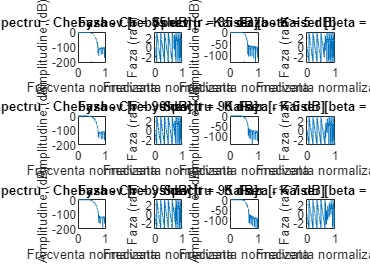


%Figura 12
figure;
subplot(3,4,1);
plot(w_chebm5/pi,20*log10(abs(h_chebm5)));
title('Spectru - Chebyshev [r = 85 dB]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(3,4,2);
plot(w_chebm5/pi,angle(h_chebm5));
title('Faza - Chebyshev [r = 85 dB]');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

subplot(3,4,3);
plot(w_ksrm1/pi,20*log10(abs(h_ksrm1)));
title('Spectru - Kaiser [beta = 5 dB]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(3,4,4);
plot(w_ksrm1/pi,angle(h_ksrm1));
title('Faza - Kaiser [beta = 5 dB]');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

subplot(3,4,5);
plot(w_cheb/pi,20*log10(abs(h_cheb)));
title('Spectru - Chebyshev [r = 90 dB]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(3,4,6);
plot(w_cheb/pi,angle(h_cheb));
title('Faza - Chebyshev [r = 90 dB]');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

subplot(3,4,7);
plot(w_ksr/pi,20*log10(abs(h_ksr)));
title('Spectru - Kaiser [r = 6 dB]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(3,4,8);
plot(w_ksr/pi,angle(h_ksr));
title('Faza - Kaiser [beta = 6 dB]');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

subplot(3,4,9);
plot(w_chebp5/pi,20*log10(abs(h_chebp5)));
title('Spectru - Chebyshev [r = 95 dB]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(3,4,10);
plot(w_chebp5/pi,angle(h_chebp5));
title('Faza - Chebyshev [r = 95 dB]');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

subplot(3,4,11);
plot(w_ksrp1/pi,20*log10(abs(h_ksrp1)));
title('Spectru - Kaiser [r = 7 dB]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(3,4,12);
plot(w_ksrp1/pi,angle(h_ksrp1));
title('Faza - Kaiser [beta = 7 dB]');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

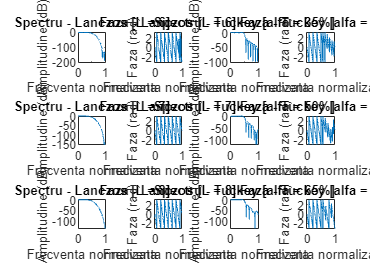


%Figura 13
figure;
subplot(3,4,1);
plot(w_lanm1/pi,20*log10(abs(h_lanm1)));
title('Spectru - Lanczos [L = 6]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(3,4,2);
plot(w_lanm1/pi,angle(h_lanm1));
title('Faza - Lanczos [L = 6]');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

subplot(3,4,3);
plot(w_tucm15/pi,20*log10(abs(h_tucm15)));
title('Spectru - Tuckey [alfa = 35%]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(3,4,4);
plot(w_tucm15/pi,angle(h_tucm15));
title('Faza - Tuckey [alfa = 35%]');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

subplot(3,4,5);
plot(w_lan/pi,20*log10(abs(h_lan)));
title('Spectru - Lanczos [L = 7]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(3,4,6);
plot(w_lan/pi,angle(h_lan));
title('Faza - Lanczos [L = 7]');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

subplot(3,4,7);
plot(w_tuc/pi,20*log10(abs(h_tuc)));
title('Spectru - Tuckey [alfa = 50%]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(3,4,8);
plot(w_tuc/pi,angle(h_tuc));
title('Faza - Tuckey [alfa = 50%]');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

subplot(3,4,9);
plot(w_lanp1/pi,20*log10(abs(h_lanp1)));
title('Spectru - Lanczos [L = 8]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(3,4,10);
plot(w_lanp1/pi,angle(h_lanp1));
title('Faza - Lanczos [L = 8]');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

subplot(3,4,11);
plot(w_tucp15/pi,20*log10(abs(h_tucp15)));
title('Spectru - Tuckey [alfa = 65%]');
xlabel('Frecventa normalizata');
ylabel('Amplitudine (dB)');

subplot(3,4,12);
plot(w_tucp15/pi,angle(h_tucp15));
title('Faza - Tuckey [alfa = 65%]');
xlabel('Frecventa normalizata');
ylabel('Faza (rad)');

function omega_c = PS_PRJ_1_Faza_2a(ng,ns) 

% Constante
% ~~~~~~~~~
   ng_min = 1 ; % 333AB
   ng_max = 8 ; % Restantieri
   ns_min = 1 ; % numarul primului student in grupa
   ns_max = 30 ; % dimensiunea maxima a grupei
   omega_c_min = 0.2*pi ; 
   omega_c_max = 0.8*pi ; 
   rng = ng_max/ng_min ; 
   rns = ns_max/ns_min ; 
%
% Parametri specifici
% ~~~~~~~~~~~~~~~~~~~
   N_min = 30 ; 
   N_max = 400 ; 
   rN = N_max/N_min ;
   if ((rng <= rN) && (rN <= rns))
      delta = ng_min*ns_max-ng_max*ns_min ;
      a = ns_max*N_min-ns_min*N_max ;
      b = ng_min*N_max-ng_max*N_min ;
   elseif (rN > rns)
      delta = ng_max*ns_max-ng_min*ns_min ;
      a = ns_max*N_min-ns_min*N_max ;
      b = ng_max*N_max-ng_min*N_min ; 
   else
      delta = ng_min*ns_min-ng_max*ns_max ; 
      a = ns_min*N_min-ns_max*N_max ; 
      b = ng_min*N_max-ng_max*N_min ; 
   end 
%
% Evaluare si normalizare suprafata de intregi
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
   [NG,NS] = meshgrid(ng_min:ng_max,ns_min:ns_max) ; 
   N = round((a*NG+b*NS)/delta) ;
   N = (N'-N_min)/(N_max-N_min) ;
%
% Generare matrice de amestecare
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
   A = [12    29    20    11    30    25     6    19
        10    11    25     9    27    13     2    17
        25     1    21    19    23    10     9    15
         1     4     3    27     7    11    25     5
         5    13    27    20    28     2    21    10
         3    15    19     6     4    21     1    24
        13     8    28    14    15    19    27     3
        19    24    22    29    13     7    20    21
        24    18     6     7    10    12    28    23
        17     3    23    12    24     5    30    20
        29    25    24    28    14    23    12    18
         6    12     5     8    18     4    24    28
        30    19     7    23     5    14    26    13
        11    23     8     5    26    30    15     7
        14    22    11    26     6    17     3     4
         9    10    12     4    25    24     8    22
        26     9    17     2     1    22    18     8
        18    30     1    22     8     6    17     2
        16    20     2    24    19     9    22    30
         3    26    13    15     9    16     4     1
         4    14    26    16     2     3    11     9
         7    28     9    25    22     8    14    16
        22     6    10    13     3    26     7    29
        27    17    29    10    12    15    19     6
        28    21    14    17    16    27     5    11
         8     7    16    21    17     1    29    25
        15    27     4    30    21    18    16    12
         2    16    18     1    29    20    23    14
        20     5    30    18    11    28    10    26
        21     2    15     3    20    29    13    27]' ;
%
% Amestecare matrice de intregi
% ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
   for rn=ng_min:ng_max
      N(rn,:) = N(rn,A(rn,:)) ;
   end 
   N = N(ng,ns) ;
%
% Generare omega_c
% ~~~~~~~~~~~~~~~~
   omega_c = omega_c_min + N*(omega_c_max-omega_c_min) ;
end